# Center of Buoyancy

This notebook is about computing the center of mass and center of buoyancy for a cross section of a boat (or other object) in 2D.  It introduces some of the MATLAB tools you will need for the boat project, and a framework for doing this kind of computation.

As you work through the notebook, take time to understand the code.

- Make changes to see what effect they have.  

- Make errors and see what happens.  

- For the MATLAB functions we use, read the documentation.

- For the functions defined at the end of the notebook, read the code!

- For each exercise, make an initial effort to do it on your own.

If you get stuck, make a reasonable effort to get unstuck -- you can learn a lot that way -- but don't stay stuck too long.  Ask for help from another student, a NINJA, or an instructor.

Then, once you get unstuck, take a minute to be sure you really understand the answer.

Remember that the goal is not just to finish the exercise and be done.  The goal is to learn what you need to know to work effectively on the project (and future projects).

Have fun!

clear all

## Defining the boat

We'll start with a hypothetical boat that's 30 cm long, 20 cm wide, and 10 cm deep.  Again, we'll use a MATLAB structure to contain information about the boat.

We'll express all quantities in this notebook using SI units, mostly meters and kilograms.

boat.L = 0.30;         % length in meters
boat.W = 0.20;         % width in meters
boat.HB = boat.W / 2;  % half breadth in meters
boat.D = 0.10;         % depth in meters

boat.mass = 1.5;       % kg
boat.n = 2;            % shape parameter (dimensionless)

Just so we get calibrated, let's compute the area, volume, and mass of a rectangular solid with these dimensions, filled with water.

max_area = boat.D * boat.W

max_area = 0.0200

max_volume = max_area * boat.L 

max_volume = 0.0060

density_water = 1025;    % kg / m^3
max_mass = max_volume * density_water

max_mass = 6.1500

Next we'll define a 2D mesh, similar to what we saw in the previous notebook.

Here's the coordinate system we'll use.

- x is the direction along the length of the boat

- y is along the width of the boat

- z is along the height/depth of the boat

dy = 0.001;   % meters
dz = 0.001;   % meters

mesh.ys = -boat.HB:dy:boat.HB;        % meters
mesh.zs = 0:dz:boat.D;                % meters

[mesh.ygrid,mesh.zgrid] = meshgrid(mesh.ys,mesh.zs);
mesh

mesh = 包含以下字段的 struct:
       ys: [-0.1000 -0.0990 -0.0980 -0.0970 -0.0960 -0.0950 -0.0940 -0.0930 -0.0920 -0.0910 -0.0900 -0.0890 -0.0880 -0.0870 -0.0860 -0.0850 -0.0840 -0.0830 -0.0820 -0.0810 -0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 … ] (1×201 double)
       zs: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 … ] (1×101 double)
    ygrid: [101×201 double]
    zgrid: [101×201 double]


dA is the area of one cell in the mesh, in square meters.

total_area = boat.W * boat.D       % m^2

total_area = 0.0200

mesh.dA = total_area / numel(mesh.ygrid)

mesh = 包含以下字段的 struct:
       ys: [-0.1000 -0.0990 -0.0980 -0.0970 -0.0960 -0.0950 -0.0940 -0.0930 -0.0920 -0.0910 -0.0900 -0.0890 -0.0880 -0.0870 -0.0860 -0.0850 -0.0840 -0.0830 -0.0820 -0.0810 -0.0800 -0.0790 -0.0780 -0.0770 -0.0760 -0.0750 -0.0740 -0.0730 … ] (1×201 double)
       zs: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 … ] (1×101 double)
    ygrid: [101×201 double]
    zgrid: [101×201 double]
       dA: 9.8517e-07


We'll use a power function to describe thahjbne shape of the hull.


$$z = D |y/HB|^n$$


where D is the depth of the boat and HB is the half breadth.

y = mesh.ys;
n = boat.n;
z = boat.D * abs(y/boat.HB).^n

z =     0.1000    0.0980    0.0960    0.0941    0.0922    0.0902    0.0884    0.0865    0.0846    0.0828    0.0810    0.0792    0.0774    0.0757    0.0740    0.0722    0.0706    0.0689    0.0672    0.0656    0.0640    0.0624    0.0608    0.0593    0.0578    0.0563    0.0548    0.0533    0.0518    0.0504    0.0490    0.0476    0.0462    0.0449    0.0436    0.0423    0.0410    0.0397    0.0384    0.0372    0.0360    0.0348    0.0336    0.0325    0.0314    0.0303    0.0292    0.0281    0.0270    0.0260


plot(y, z)

Next we will use a* logical matrix* to represent the cells that are inside and outside the boat.  A logical matrix (also called a boolean matrix) contains only the values 0 and 1, where 0 represents "false" and 1 represents "true".

You create ahjul logical matrix by applying comparison operations to numerical matrixes.  In the following example, **hull** has the same shape as **mesh.zgrid**; it contains 1 (true) wherever the **z** coordinate in the mesh exceeds the function we just computed, and 0 (false) otherwise.

hull = mesh.zgrid > z

hull = 101×201 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

If you look at the values in **hull**, they will seem upside-down.  That's a side effect of the way we defined the mesh.

We can visualize the hull using **image**, which is a MATLAB function that treats a matrix as an image.  **redmap** is a colormap that uses red to represent 1 and white to represent 0.

**flipud** is a MATLAB function that flips a matrix upside-down.

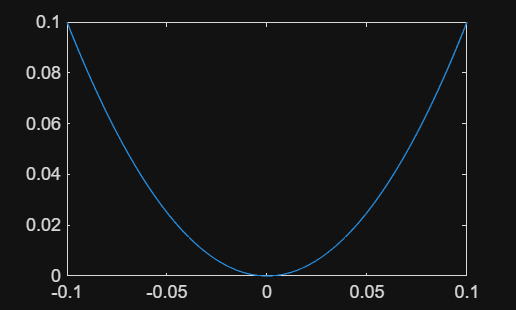

redmap = [1,1,1;1,0,0];
colormap(redmap);

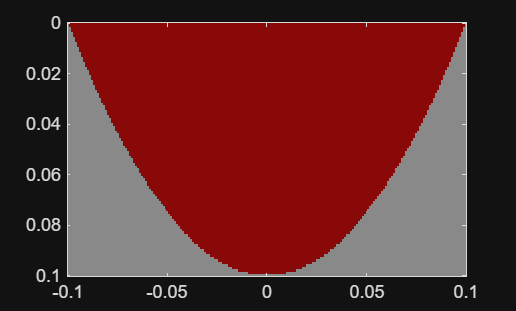

image(mesh.ys,mesh.zs,flipud(hull),'AlphaData',0.5);

**Exercise 1:** Use the code from the previous section to fill in the body of **computeHull** and **plotMatrix** , below, and then test them using the following lines of code.

Note: If you run this code now, it will run, but it won't do the right thing until you fix **computeHull**.

boat.hull = computeHull(mesh,boat);

y =    -0.1000   -0.0990   -0.0980   -0.0970   -0.0960   -0.0950   -0.0940   -0.0930   -0.0920   -0.0910   -0.0900   -0.0890   -0.0880   -0.0870   -0.0860   -0.0850   -0.0840   -0.0830   -0.0820   -0.0810   -0.0800   -0.0790   -0.0780   -0.0770   -0.0760   -0.0750   -0.0740   -0.0730   -0.0720   -0.0710   -0.0700   -0.0690   -0.0680   -0.0670   -0.0660   -0.0650   -0.0640   -0.0630   -0.0620   -0.0610   -0.0600   -0.0590   -0.0580   -0.0570   -0.0560   -0.0550   -0.0540   -0.0530   -0.0520   -0.0510


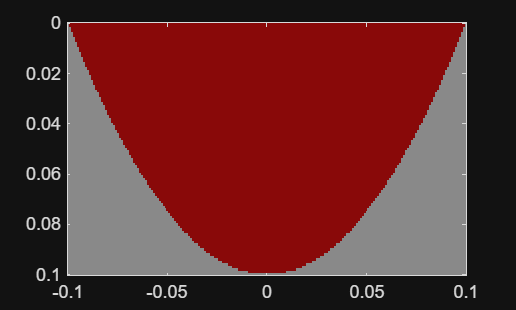

plotMatrix(boat.hull,mesh,redmap);

**Exercise 2:** 

- Use **matrixSum** (which we saw in the previous notebook) to compute the total number of cells in this hull section.  

- Compute the area of the section in square meters.  Does it seem about right compared to **max_area**?

- Assuming that the section of the boat is the same from bow to stern, compute the total volume of the hull.  Does it seem about right compared to **max_volume**?

- Compute the total mass of water the boat would displace if fully submerged.  Does it seem about right compared to **max_mass**?

What happens to the shape of the hull as we increase the shape parameter, **n**?

boat.num_cells = matrixSum(boat.hull)

boat = 包含以下字段的 struct:
            L: 0.3000
            W: 0.2000
           HB: 0.1000
            D: 0.1000
         mass: 1.5000
            n: 2
         hull: [101×201 logical]
    num_cells: 13420


areahull = boat.num_cells * dy * dz % seems about right

areahull = 0.0134

volumehull = areahull * boat.L 

volumehull = 0.0040

masshull = volumehull * density_water

masshull = 4.1266

## Center of mass

To compute center of mass, let's use **boat.hull** to compute a matrix of masses.

Multiplying a logical matrix by a scalar yields a numerical matrix.

boat.mass_per_cell = boat.mass / boat.num_cells;
masses = hull * boat.mass_per_cell;

**Exercise 3:**

- Use **matrixSum** to compute the total mass of **masses**, and confirm that it matches the total mass of the boat, **boat.mass**.

- Fill in the body of **centerOfMass2**, below, so it computes the center of mass in the y-z plane.

- Compute the center of mass for the hull.  What do you expect the y coordinate to be?  Does the z coordinate seem about right?

- What happens to the center of mass as we increase the shape parameter, **n**?

totalmasses = matrixSum(masses)

totalmasses = 1.5000

COM_hull = centerOfMass2(masses,mesh)

COM_hull =    -0.0000    0.0603


%closer to the bottom tip

**Exercise 4:** Add 0.5 kg of ballast at the bottom of the boat and recompute the center of mass.  Does the COM shift in the way you expect?

Hint: make a copy of **addMass2** from the previous notebook and modify it to work in the y-z plane.


[abc index_z] = min(z)

abc = 0

index_z = 101


position_02 = [y(index_z),abc] %under this equation( z = boat.D * abs(y/boat.HB).^n), index_z will be = index_y. 

position_02 =      0     0



masses = addMass2(0.5,position_02,masses,mesh)

masses =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

COM_weight2 = centerOfMass2(masses, mesh)

COM_weight2 =    -0.0000    0.0452


## Representing the water

In the same way we built a logical matrix to represent the hull, we'll create another to represent the water.

We'll parameterize the waterline using **theta** to indicate the angle of the water relative to the deck of the boat, and **d** to represent the height of the water, also relative to the deck.

Here's an example:

d = 0.05; 
theta = 10;

y = mesh.ys;
z = tand(theta) .* y + d

z =     0.0324    0.0325    0.0327    0.0329    0.0331    0.0332    0.0334    0.0336    0.0338    0.0340    0.0341    0.0343    0.0345    0.0347    0.0348    0.0350    0.0352    0.0354    0.0355    0.0357    0.0359    0.0361    0.0362    0.0364    0.0366    0.0368    0.0370    0.0371    0.0373    0.0375    0.0377    0.0378    0.0380    0.0382    0.0384    0.0385    0.0387    0.0389    0.0391    0.0392    0.0394    0.0396    0.0398    0.0399    0.0401    0.0403    0.0405    0.0407    0.0408    0.0410



plot(y,z)

Now we'll compute a logical matrix that's 1 where there's water and 0 elsewhere.

water = mesh.zgrid < z;

And here's what it looks like.

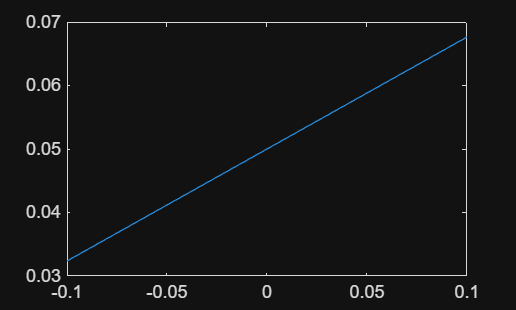

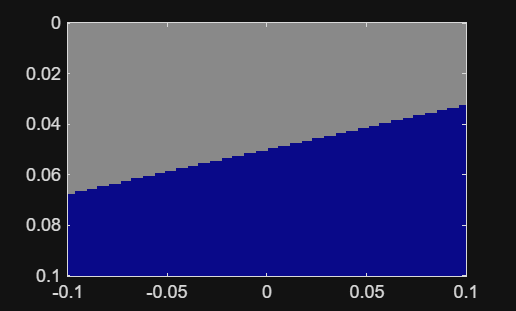

bluemap = [1,1,1; 0,0,1];
plotMatrix(water,mesh,bluemap);

You might wonder why we are rotating the water rather than rotating the boat.  The short answer is that it was easier to write the program this way.  There are definitely pros and cons to this decision.  In your code for the project, you might consider rotating the boat instead, and see if you think it's a better design.

**Exercise 5:** Use the code from the previous section to fill in the body of **computeWater**, below, and test it below using the following code.

Note: If you run this code now, it will run, but it won't do the right thing until you fix **computeWater**.

water = computeWater(d,theta,mesh);

z =     0.0324    0.0325    0.0327    0.0329    0.0331    0.0332    0.0334    0.0336    0.0338    0.0340    0.0341    0.0343    0.0345    0.0347    0.0348    0.0350    0.0352    0.0354    0.0355    0.0357    0.0359    0.0361    0.0362    0.0364    0.0366    0.0368    0.0370    0.0371    0.0373    0.0375    0.0377    0.0378    0.0380    0.0382    0.0384    0.0385    0.0387    0.0389    0.0391    0.0392    0.0394    0.0396    0.0398    0.0399    0.0401    0.0403    0.0405    0.0407    0.0408    0.0410


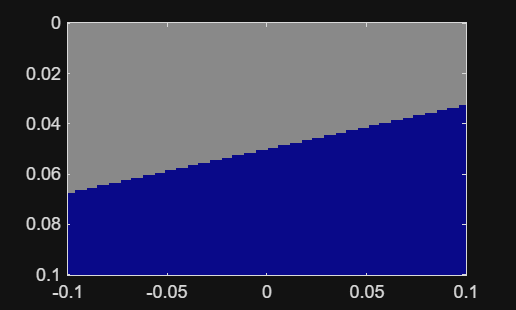

plotMatrix(water,mesh,bluemap)

## Computing the submerged region

At this point we have a logical matrix that represents the hull and another logical matrix that represents the water.  We can use logical operators to compute the union and intersection of logical matrices.

If A and B are logical matrices

- **A&B** finds the intersection; that is, the cells that are in both regions, "A and B".

- **A|B** finds the union; that is, cells that are in either region, "A or B"

So we can compute the submerged region like this

sub_region = boat.hull & water;

And plot it like this

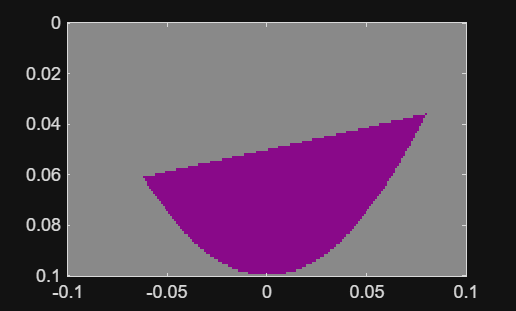

purplemap = [1,1,1; 1,0,1];
plotMatrix(sub_region,mesh,purplemap);

## Center of buoyancy

The center of buoyancy is the center of mass of the displaced water.  The density of well mixed water is very close to constant, so we can compute the center of buoyancy by computing the center of mass of **sub_region**.

COB = centerOfMass2(sub_region,mesh)

COB =     0.0088    0.0313


**Exercise 6:** Test this code with a range of values for theta and d.  Does the COB seem to be in the right place?

What happens when theta exceeds 90 degrees?  Can you fix **computeWater** so it handles this case correctly?

water = computeWater(d,170,mesh);

z =     0.0676    0.0675    0.0673    0.0671    0.0669    0.0668    0.0666    0.0664    0.0662    0.0660    0.0659    0.0657    0.0655    0.0653    0.0652    0.0650    0.0648    0.0646    0.0645    0.0643    0.0641    0.0639    0.0638    0.0636    0.0634    0.0632    0.0630    0.0629    0.0627    0.0625    0.0623    0.0622    0.0620    0.0618    0.0616    0.0615    0.0613    0.0611    0.0609    0.0608    0.0606    0.0604    0.0602    0.0601    0.0599    0.0597    0.0595    0.0593    0.0592    0.0590


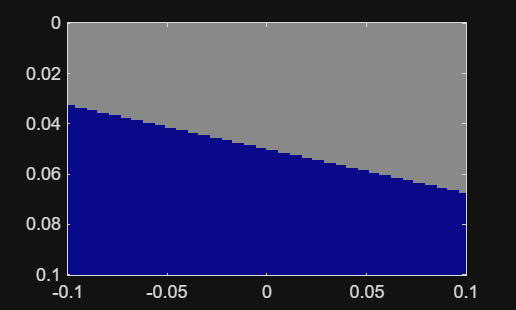

plotMatrix(water,mesh,bluemap);

## Function definitions

function hull = computeHull(mesh,boat)
    % computeHull: compute the shape of the hull
    % mesh: structure that contains y
    % boat: structure that contains n
    % returns: logical matrix
    
    % TODO: fill this in
    y = mesh.ys
    z = boat.D * abs(y/boat.HB).^ boat.n;
    hull = mesh.zgrid > z ;
   

end

function plotMatrix(A,mesh,cmap)
    % plotMatrix: plots a matrix using image
    % A: matrix
    % mesh: srtruct containing ys and zs
    % cmap: Colormap
    colormap(cmap);
    image(mesh.ys,mesh.zs,flipud(A),'AlphaData',0.5);
end

function M = matrixSum(A)
    % matrixSum: returns total of all elements in the matrix
    % A: matrix
    % returns: scalar
    
    % normally sum(m) computes the sums of the columns
    % selecting m(:) flattens the matrix and computes the sum of all elements
    % see https://stackoverflow.com/questions/1721987/what-are-the-ways-to-sum-matrix-elements-in-matlab
    M = sum(A(:));
end

function COM = centerOfMass2(masses,mesh)
    % centerOfMass2: computes center of mass in 2D
    % masses: matrix of masses
    % mesh: structure containing ygrid and zgrid
    % returns: Vector [ycom,zcom]
    M = matrixSum(masses);
    ycom = matrixSum(masses .* mesh.ygrid) / M;
    zcom = matrixSum(masses .* mesh.zgrid) / M;
    COM = [ycom,zcom];
end

function masses = addMass2(mass,position,masses,mesh) 
    
index_y = closestIndex(position(1,1), mesh.ygrid(1,:));
 
index_z = closestIndex(position(1,2), mesh.zgrid(:,1));
 
masses(index_z, index_y) = masses (index_z, index_y) + mass;
    masses = masses;
end

function index = closestIndex(coord,grid)
    % closestIndex: finds the index of the grid point closest to coord
    % coord: scalar coordinate
    % grid: matrix of coordinates
    % returns: integer index
    
    % see: https://www.mathworks.com/matlabcentral/answers/152301-find-closest-value-in-array
    [c index] = min(abs(coord-grid));
end

function water = computeWater(d,theta,mesh)
    % water: compute the level of the water
    % d: depth of waterline in meters
    % theta: angle of waterline in degrees
    % mesh: structure containing ys and zgrid
    % returns: logical matrix
    
    % TODO: fill this in

y = mesh.ys;
z = tand(theta) .* y + d
    
    water = mesh.zgrid < z;
end






